# **EEG DURING SLEEP**

### Loading the signal

The 9-hour signal was recorder with a sampling frequency of 512 Hz. The first and the last two minutes were arbitrary cut due to possible misrecordings.

load("record.mat");
EEG = double(record);
clear record
fs_EEG = 512;
EEG = EEG(2*60*fs_EEG:end);
EEG = EEG((length(EEG)/fs_EEG - 2*60)*fs_EEG:-1:1);
N = length(EEG);

### Power Spectrum 

To understand which kind of filters to use PSD was computed with Welch's Method (Hann's Window) with 50% overlap

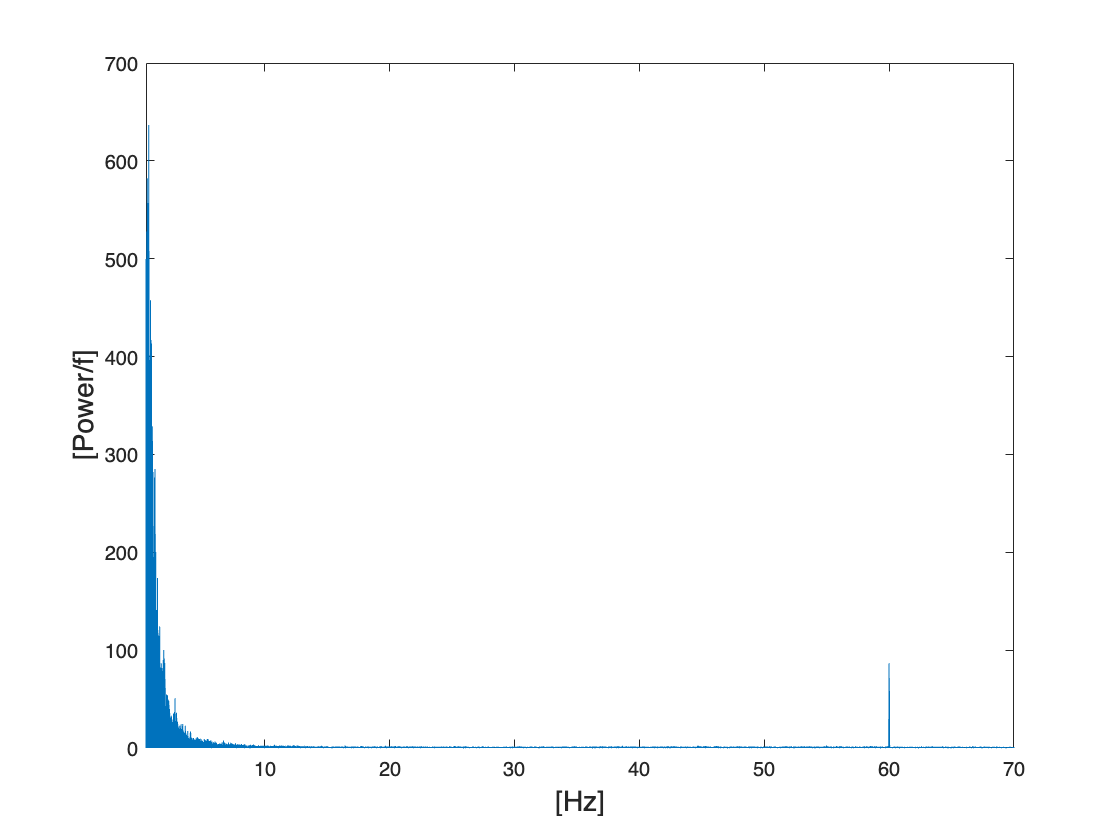

noverlap = 0.5*N;
EEG = detrend(EEG);
[Pxx, freq1] = pwelch(EEG, hanning(length(EEG)), noverlap, [], fs_EEG);

figure
plot(freq1, Pxx)
xlim([0.5,70]);
xlabel('[Hz]', fontsize=14);
ylabel('[Power/f]',fontsize=14);

### Filtering 

We noticed a net infererence at 60Hz, so we design an IIR notch filter. Then, according to literature we extracted the band of interest of EEG

- Low Pass filter at 70 Hz  

- High Pass filter at 0.5 Hz 

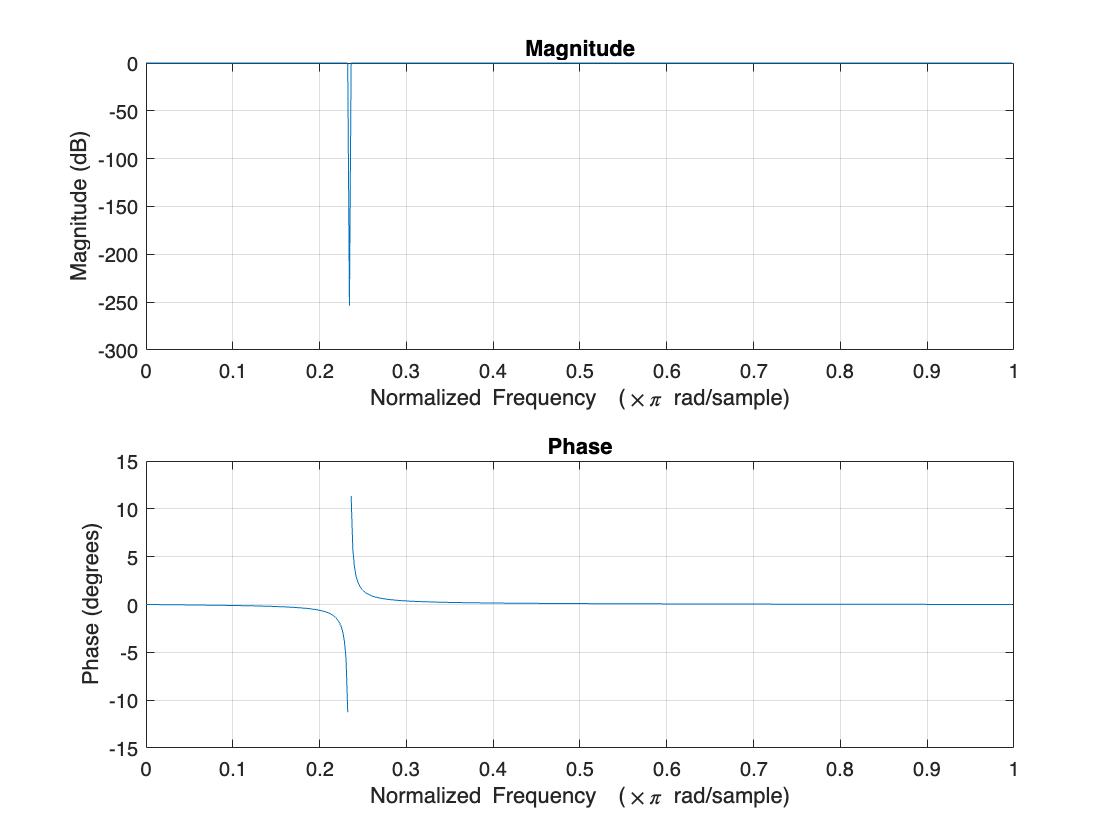

%Notch Filter
[b,a] = iirnotch(60/(fs_EEG/2),0.2/(fs_EEG/2));
EEG = filtfilt(b,a, EEG);

%Filter specs
figure 
freqz(b,a);

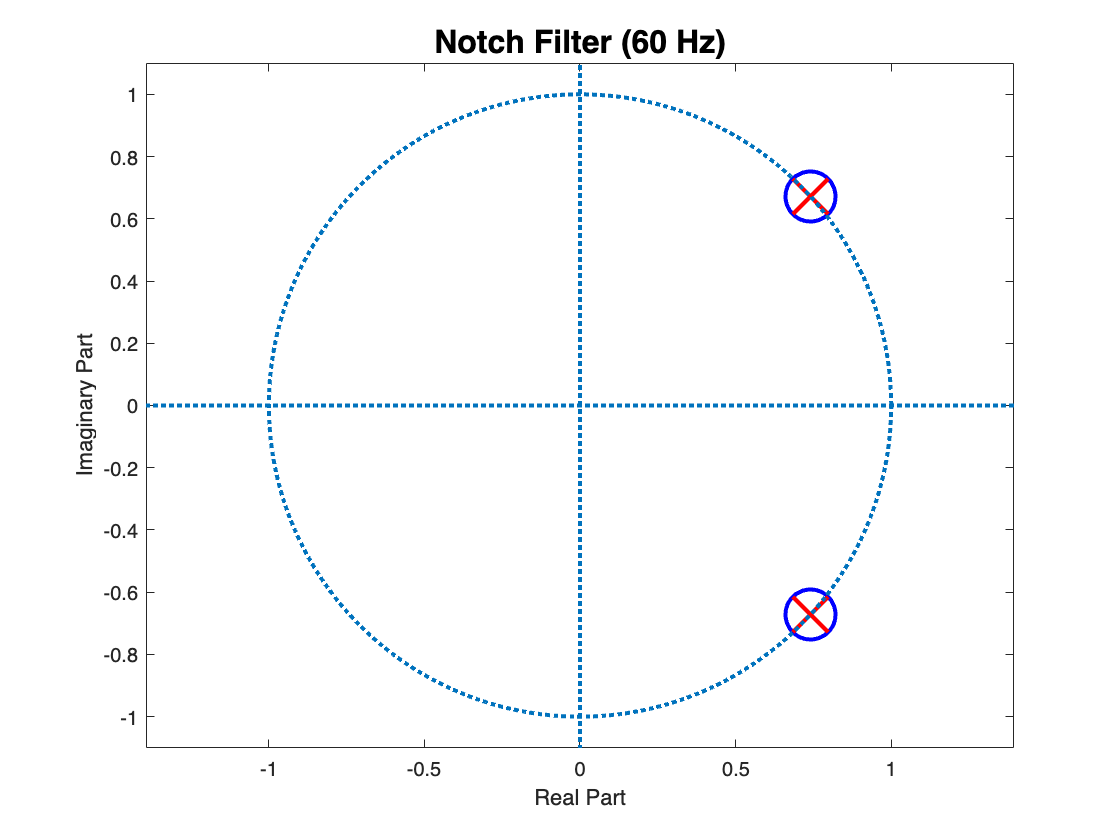

figure 
[hz,hp,hl]=zplane(b,a);
set(hz, markerSize=25, color='b',linewidth=2);
set(hp, markerSize=25, color='r',linewidth=2);
set(hl,linewidth=2)
title('Notch Filter (60 Hz)','FontSize',16)

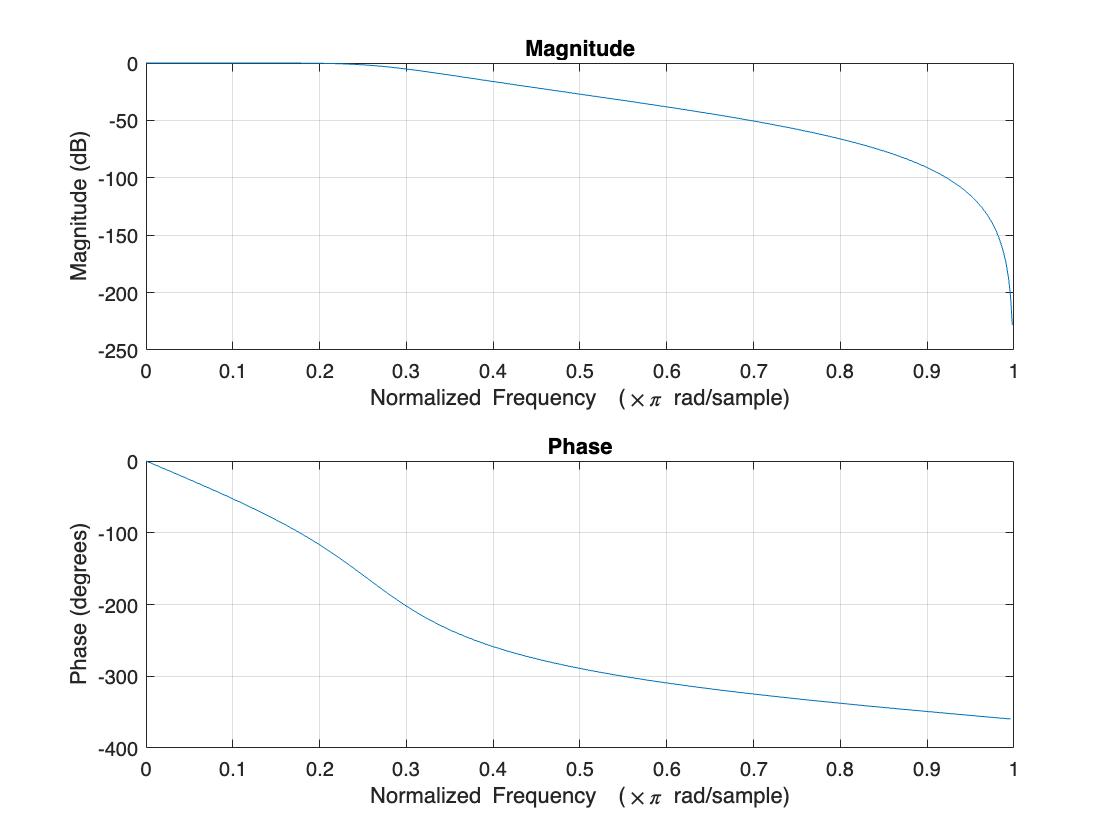

%Low-pass
filter_order = 4;
f_cut = 70;
wc = f_cut/(fs_EEG/2);
[b,a] = butter(filter_order,wc,'low');
EEG = filtfilt(b,a,EEG);

%Filter specs
figure
freqz(b,a);

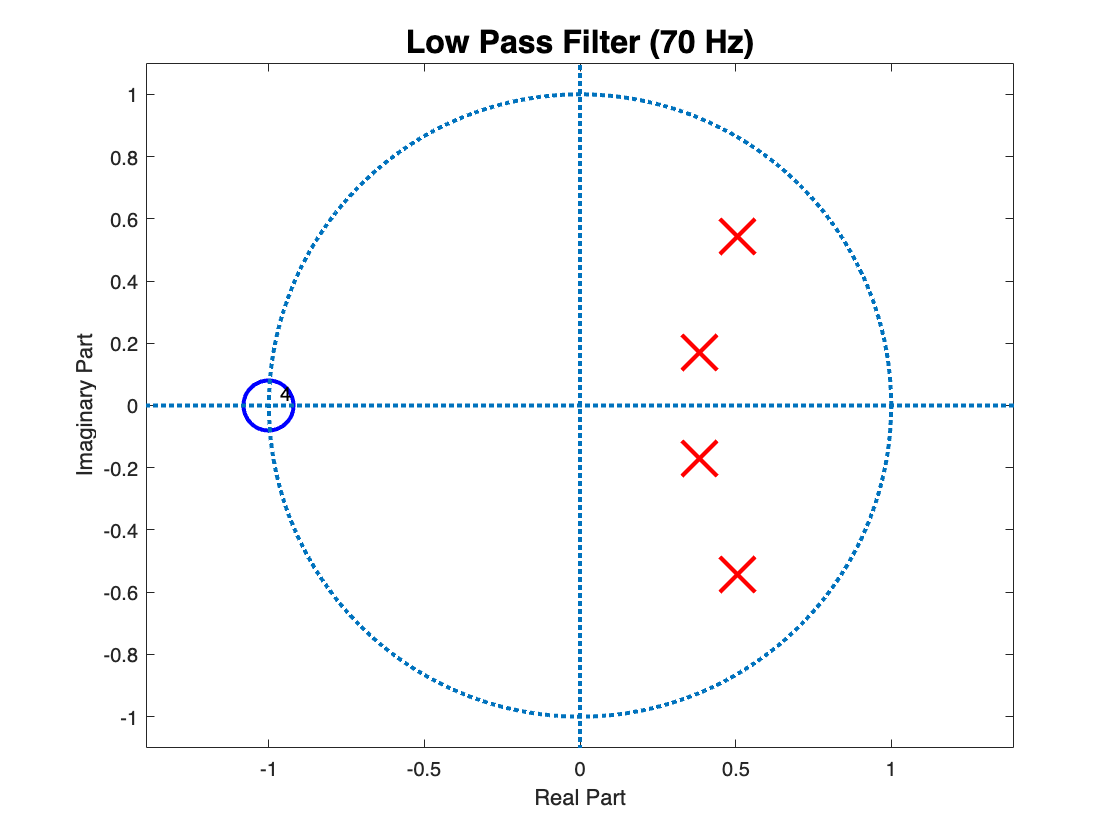

figure 
[hz,hp,hl]=zplane(b,a);

set(hz, markerSize=25, color='b',linewidth=2);
set(hp, markerSize=25, color='r',linewidth=2);
set(hl,linewidth=2)
title('Low Pass Filter (70 Hz)','FontSize',16)

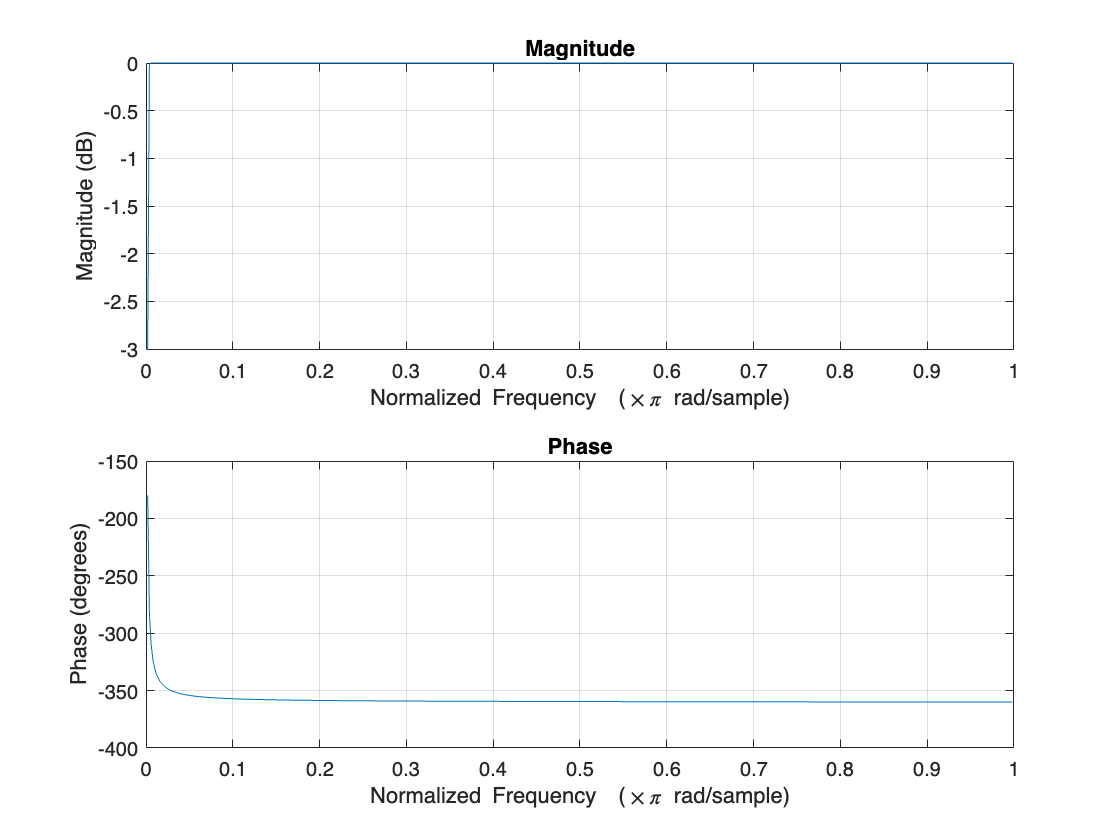

%High-pass
filter_order = 4;
f_cut = 0.5;
wc = f_cut/(fs_EEG/2);
[b,a] = butter(filter_order,wc,'high');
EEG = filtfilt(b,a,EEG);

%Filter specs
figure
freqz(b,a);

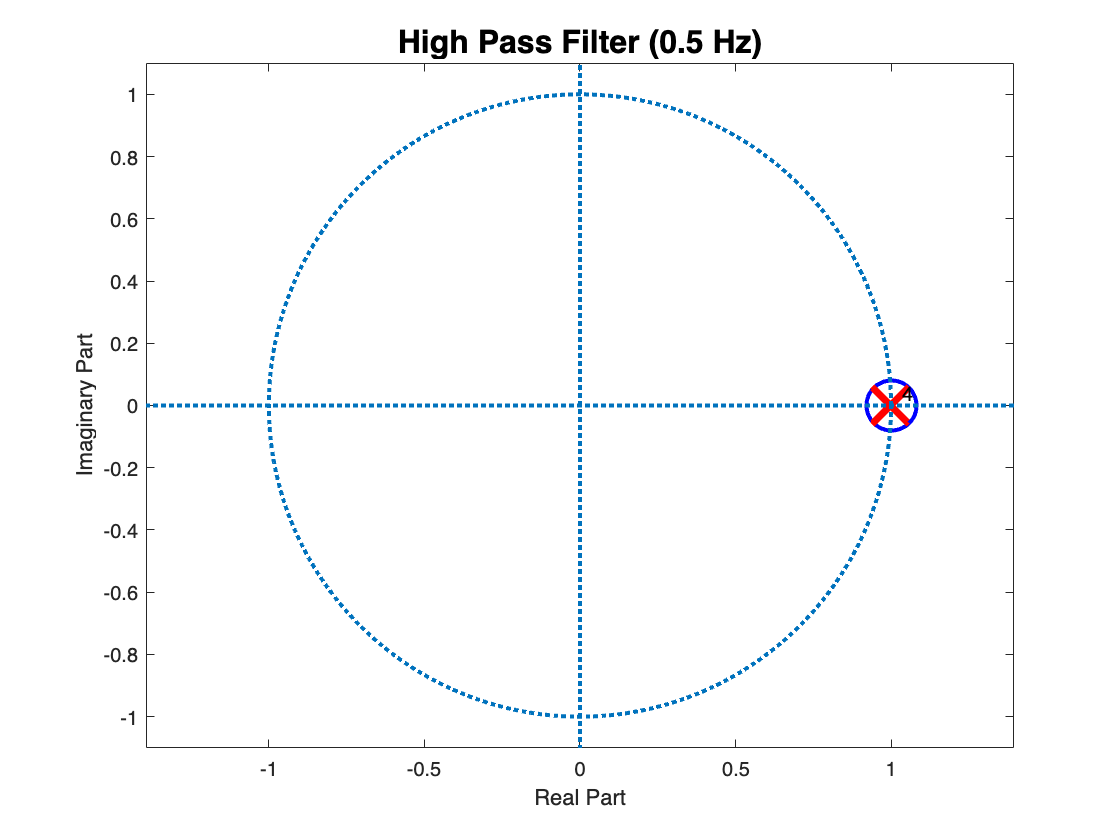

figure 
[hz,hp,hl]=zplane(b,a);
set(hz, markerSize=25, color='b',linewidth=2);
set(hp, markerSize=25, color='r',linewidth=2);
set(hl,linewidth=2)
title('High Pass Filter (0.5 Hz)','FontSize',16)

After filtering we plot again the power spectrum to see the results of pre-processing 

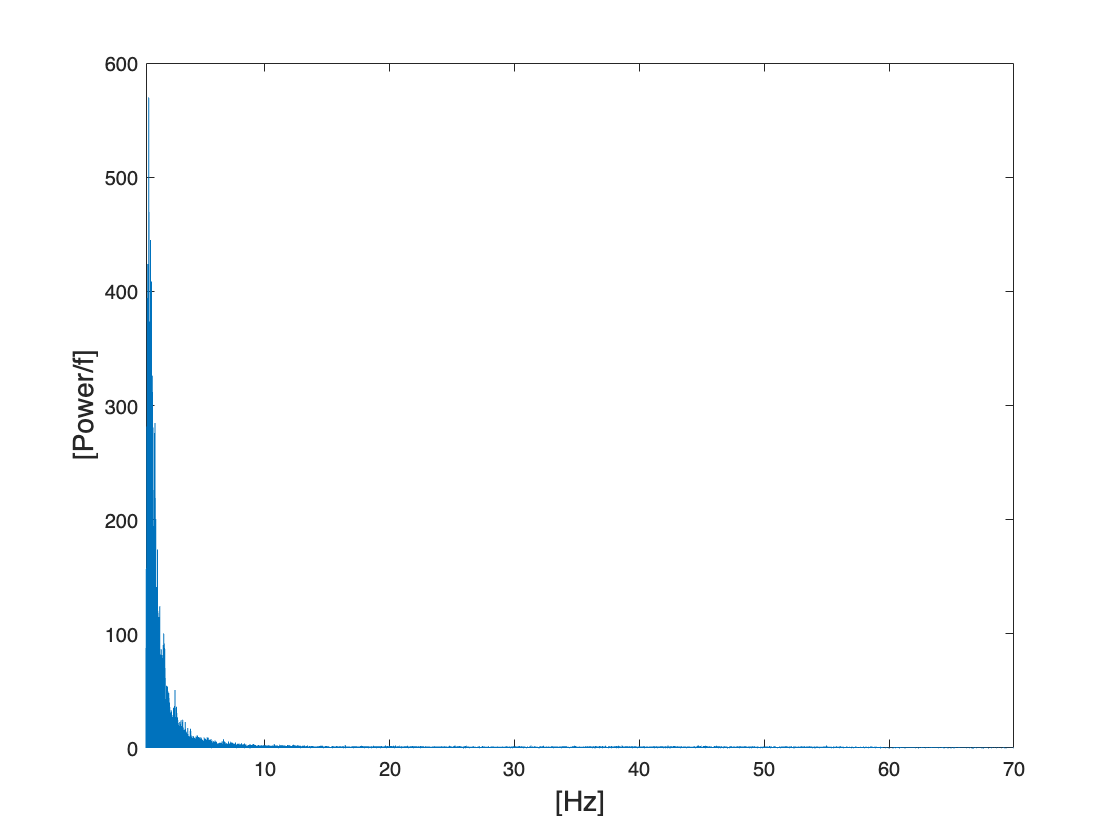

noverlap = 0.5*N;
[Pxx, freq1] = pwelch(EEG, hanning(length(EEG)), noverlap, [], fs_EEG);

figure
plot(freq1, Pxx)
xlabel('[Hz]', fontsize=14);
ylabel('[Power/f]',fontsize=14);
xlim([0.5 70])

### Dividing into epochs and PSD computation

9-hour signal was divided into 30-second epochs to better analyze sleep stages.

lep = 30; %seconds 
ep_samples = lep*fs_EEG; %number of samples for each epoch

%EEG bands
f_vect_high = [8 4 2.5 18];
f_vect_low = [14 8 4 25];
names = ["alpha", "theta", "delta", "beta"];

For each epoch we calculate the PSD of all the frequency content and for each band of interest (alpha, theta, delta). To determine the power of each band we calculated the variance (according to the Parseval Theorem) and to estimate how present is each band of interest, we computed the ratio between the variance of PSD of that band and the variance of the whole PSD.  

PSD for each epoch was computed using Welch's method, with a 20-second overlapping Hann's window.

ep = cell(1, floor(length(EEG)/ep_samples)); %cell array of the epochs
var = cell(floor(length(EEG)/ep_samples), 3); %cell array of the variances
perc = cell(floor(length(EEG)/ep_samples), 3); %cell array of the percentages

for i = 1:floor(length(EEG)/ep_samples)
    %Epochs extraction
    ep{i} = EEG(1+ep_samples*(i-1):ep_samples*(i));
    ep{i} = detrend(ep{i});

    %Whole frequencies PSD with Welch
    noverlap = 20*fs_EEG;
    [Pxx_ep, freq_ep] = pwelch(ep{i}, hanning(ep_samples), noverlap, [], fs_EEG);
    freq1_ep = 0:fs_EEG/length(Pxx_ep):fs_EEG/2;


    for j = 1 : length(f_vect_low)
        filter_order = 4;
        %Low-pass
        f_cut = f_vect_low(j);
        wc = f_cut/(fs_EEG/2);
        [b1,a1] = butter(filter_order,wc,'low');
        ep_lp = filtfilt(b1,a1,ep{i});

        %High-pass
        f_cut = f_vect_high(j);
        wc = f_cut/(fs_EEG/2);
        [b1,a1] = butter(filter_order,wc,'high');
        ep_filt = filtfilt(b1,a1,ep_lp);

        %PSD with Welch for the j-band 
        noverlap = 20*fs_EEG/2;
        [Pxx, freq] = pwelch(ep_filt, hanning(ep_samples), noverlap, [], fs_EEG);
        
        %Variance and percentage calculation
        var{i,j} = trapz(freq, Pxx);
        perc{i, j} = trapz(freq, Pxx)/trapz(freq_ep, Pxx_ep);
    end
end

var = cell2table(var, 'VariableNames', names);
save("variances.mat", "var");

perc = cell2table(perc, 'VariableNames', names);
save("percentages.mat", "perc");

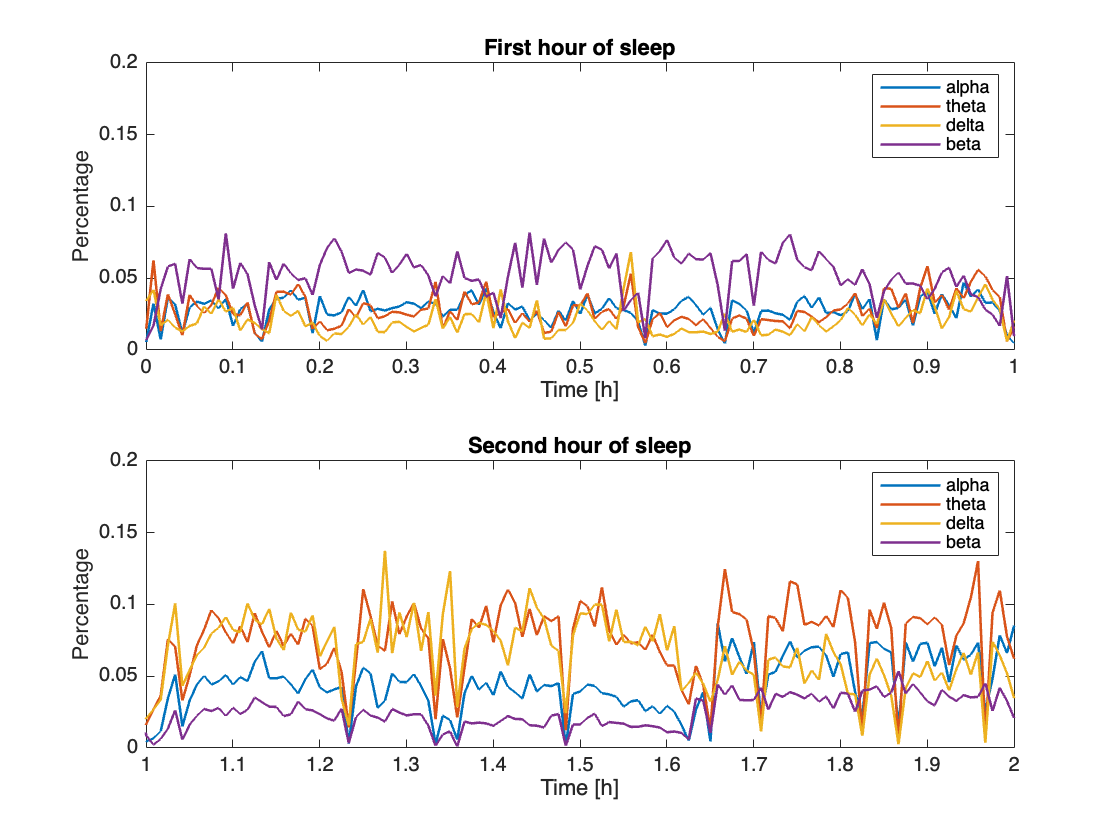

%Plot of the percentages for each frequency band in 
% the first hour and the second one as an example
lim = [0 1];
figure
t = (1:lep:lep*floor(length(EEG)/ep_samples))/3600;
subplot(2,1,1)
plot(t,perc.alpha,'LineWidth',1.3),
ylim([0,0.2]), 
xlim(lim);

hold on
plot(t,perc.theta, 'LineWidth',1.3);
ylim([0,0.2]), 
xlim(lim);

hold on 
plot(t,perc.delta, 'LineWidth',1.3),
ylim([0,0.2]), 
xlim(lim);

hold on 
plot(t,perc.beta, 'LineWidth',1.3),
ylim([0,0.2]), 
xlim(lim);

xlabel('Time [h]')
ylabel('Percentage')
title('First hour of sleep')
legend('alpha', 'theta', 'delta', 'beta')

lim = [1 2];
subplot(2,1,2)
plot(t,perc.alpha,'LineWidth',1.3),
ylim([0,0.2]), 
xlim(lim);

hold on
plot(t,perc.theta, 'LineWidth',1.3);
ylim([0,0.2]), 
xlim(lim);

hold on 
plot(t,perc.delta, 'LineWidth',1.3),
ylim([0,0.4]), 
xlim(lim);

hold on 
plot(t,perc.beta, 'LineWidth',1.3),
ylim([0,0.2]), 
xlim(lim);

xlabel('Time [h]')
ylabel('Percentage')
title('Second hour of sleep')

legend('alpha', 'theta', 'delta', 'beta')

### Sleep stages classification

Sleep stages are characterized by the presence some certain bands. So, we classified epochs due to the amount of presence of the bands of interest in it.

For each epoch, we calculate the maximum and the minumun percentage of variance and we report in a cell array the most predominant band and the less predodominant one for each epoch.

st = 1:5;
domTab = cell(floor(length(EEG)/ep_samples),3);
for i = 1:floor(length(EEG)/ep_samples)

    h = perc{i,:} == min(perc{i,:});
    j = perc{i,:} == max(perc{i,:});
    
    domTab{i,1} = perc.Properties.VariableNames{h};
    domTab{i,2} = perc.Properties.VariableNames{j};
    
end

Sleep period can be subdivided into five stages: 

- Awake 

- Stage NREM1

- REM

- Stage NREM 2

- Stage NREM 4

Ordered from the maximum level of consciusness to the minumum one.

stages = [{'awake'}, {'stage NREM1'}, {'REM'}, {'stage NREM2'}, {'stage NREM3'}]; 
domArr = zeros(length(domTab), 2);

for i = 1:floor(length(EEG)/ep_samples)
    if domTab{i,1} == "alpha"
        domArr(i,1) = 1;
    end

    if domTab{i,2} == "alpha"
        domArr(i,2) = 1;
    end

    if domTab{i,1} == "theta"
           domArr(i,1) = 2;
    end

    if domTab{i,2} == "theta"
            domArr(i,2) = 2;
    end

    if domTab{i,1} == "delta"
            domArr(i,1) = 3;
    end

    if domTab{i,2} == "delta"
            domArr(i,2) = 3;
    end

    if domTab{i,1} == "beta"
            domArr(i,1) = 4;
    end

    if domTab{i,2} == "beta"
            domArr(i,2) = 4;
    end

end

%alpha 1, theta 2, delta 3, beta 4

for i = 1:floor(length(EEG)/ep_samples)
    if i+5 < length(domArr)
        a = length(find(domArr(i:i+5, 2) == 1)); %alpha count max
        b = length(find(domArr(i:i+5, 2) == 2)); %theta count max
        c = length(find(domArr(i:i+5, 2) == 3)); %delta count max
        d = length(find(domArr(i:i+5, 1) == 1)); %alpha count min
        e = length(find(domArr(i:i+5, 1) == 3)); %delta count min
        f = length(find(domArr(i:i+5, 1) == 4)); %beta count min
        g = length(find(domArr(i:i+5, 2) == 4)); %beta count max 

        if a >= 3 || g >= 3 
            for j = i:i+5
                domTab{i,3} = 5; %awake
            end
        end

        if b>=3 && a >= c 
            for j = i:i+5
                domTab{i,3} = 4; %REM
            end
        end

        if b >= 3 && d>=e
            for j = i:i+5
                domTab{i,3} = 2; %NREM 2 sleep
            end
        end

        if c >= 3 && d >= 5 
            for j = i:i+5
                domTab{i,3} = 1; %NREM 3 deep sleep
            end
        end


        if c >= 3 && f>=5 
            for j = i:i+5
                domTab{i,3} = 1; %NREM 3 deep sleep
            end
        end
        

      
    end

    if isempty(domTab{i, 3}) %NREM 1 light sleep
        domTab{i,3} = 3;
    end

end

### Hypnogram

app=cell2mat(domTab(:,3));
EpTogether = 10;
for i = 1:EpTogether:length(app)-EpTogether
    count=zeros(5,1);
    for k=1:5
        for j=i:i+EpTogether-1
            if app(j)==k
                count(k)=count(k)+1;
            end
        end     
    end
    [pp,p]=max(count);
    for j=i:i+EpTogether-1
        app(j,1)=p;
    end
end

for h = 1:1060
    hypno(h) = domTab{h,3};
end

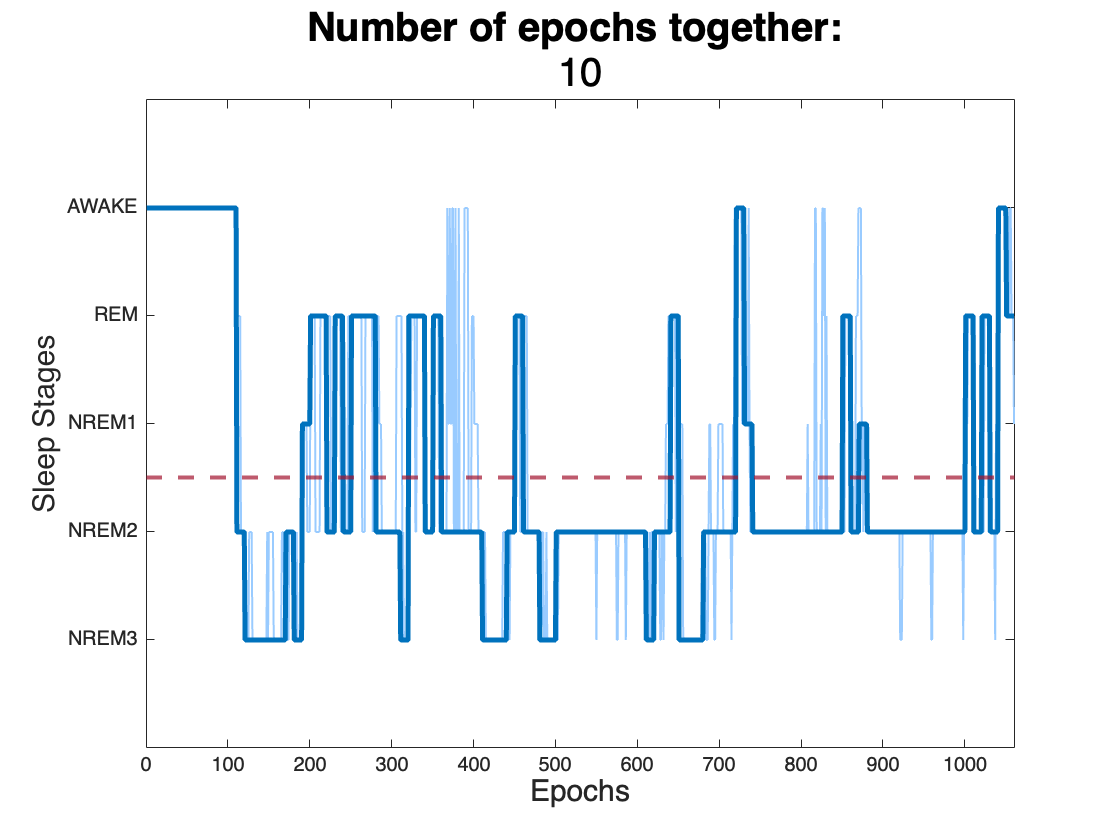

figure 
plot(1:1060, hypno, 'LineWidth',1,'Color','#99CBFF')

hold on

for h = 1:1060
    hypno(h) = app(h);
end

plot(1:1060, hypno,'LineWidth',2.5,'Color','#0072BD')

hold on

yline(2.5,'--','LineWidth',2,'Color','#A2142F')

title('Number of epochs together: ',EpTogether, 'FontSize', 20)
xlabel('Epochs','FontSize',15)
ylabel('Sleep Stages', 'FontSize',15)
set(gca,'YTick',0:5);
yticklabels({'';'NREM3';'NREM2';'NREM1';'REM';'AWAKE'})
ylim([0,6]);
xlim([0,1060])

domTab = cell2table(domTab, 'VariableNames', ["Less Dominant Band", "Dominant band", "Stage"]);
save("dom_waves.mat", "domTab");